## **Lab 08: Z-Transform Analysis**

clc; 
clear;
close all;

%%Task 1: Symbolic Z-Transforms
syms n z

x1_n = heaviside(n);          
x2_n = (0.5)^n * heaviside(n); % 0.5^n u[n]
x3_n = dirac(n); % delta[n]

% Convertign to z domain using symbolic toolbox
X1_z = ztrans(x1_n, n, z);
X2_z = ztrans(x2_n, n, z);
X3_z = ztrans(x3_n, n, z);
check_x1 = iztrans(X1_z, z, n);

fprintf('Task 1 Results:\n');

Task 1 Results:


disp(X1_z); disp(X2_z); disp(X3_z);

$$\frac{1}{z-1}+\frac{1}{2}$$

$$\frac{1}{2\,z-1}+\frac{1}{2}$$

$$\mathrm{ztrans}\left(\delta (n),n,z\right)$$

%% Task 2: Eigenfunction Property

n_vec = 0:40;
omega = pi/4;
x_input = exp(1j * omega * n_vec); 

% System coefficients from: y[n] - 0.5y[n-1] = x[n] 
num = 1; 
den = [1, -0.5]; 

% Run the signal through the system
y_output = filter(num, den, x_input);

% Analytical check
z_val = exp(1j * omega);
H_val = 1 / (1 - 0.5 * z_val^-1);

% This is the theoretical output
y_theory = H_val * x_input;

% Display H in rectangular form 
fprintf('Task 2: Calculated H(ej*pi/4) in rectangular form:\n');

Task 2: Calculated H(ej*pi/4) in rectangular form:


disp(H_val); 

   1.1907 - 0.6512i



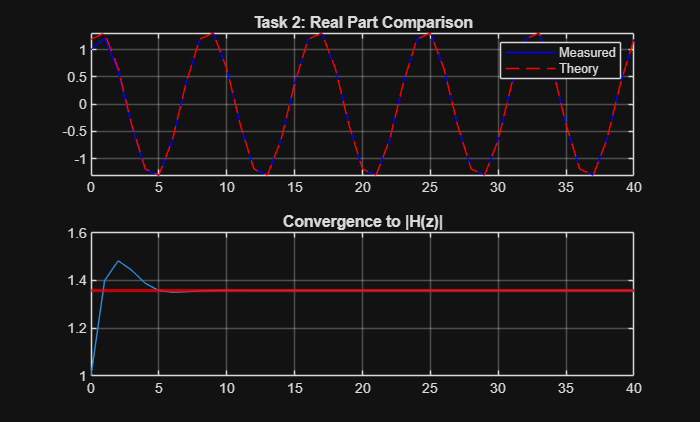


% Visual Verification
figure(1);
subplot(2,1,1);
plot(n_vec, real(y_output), 'b', n_vec, real(y_theory), 'r--');
title('Task 2: Real Part Comparison'); 
legend('Measured', 'Theory');
grid on;

subplot(2,1,2);
plot(n_vec, abs(y_output ./ x_input));
yline(abs(H_val), 'r', 'LineWidth', 2);
title('Convergence to H(z)');
grid on;

%% Task 3: Loop vs Z-Transform
% Manually solving the difference equation
N_samples = 10;
y_loop = zeros(1, N_samples);
impulse = [1, zeros(1, N_samples-1)]; % x[n] = delta[n]

% Recursive loop 
for k = 1:N_samples
    if k == 1
        y_loop(k) = impulse(k);
    else
        y_loop(k) = impulse(k) + 0.8 * y_loop(k-1);
    end
end

% Analytical check using inverse Z-transform
% H(z) = 1 / (1 - 0.8z^-1) -> h[n] = (0.8)^n u[n]
n_idx = 0:N_samples-1;
y_analytical = (0.8).^n_idx;

% format result into a table
ResultsTable = table(n_idx', y_loop', y_analytical', ...
    'VariableNames', {'n', 'Loop Method', 'Z-Transform Method'});
disp('Task 3: Comparison Table');

Task 3: Comparison Table


disp(ResultsTable);

    n    Loop Method    Z-Transform Method
    _    ___________    __________________

    0            1                 1      
    1          0.8               0.8      
    2         0.64              0.64      
    3        0.512             0.512      
    4       0.4096            0.4096      
    5      0.32768           0.32768      
    6      0.26214           0.26214      
    7      0.20972           0.20972      
    8      0.16777           0.16777      
    9      0.13422           0.13422      



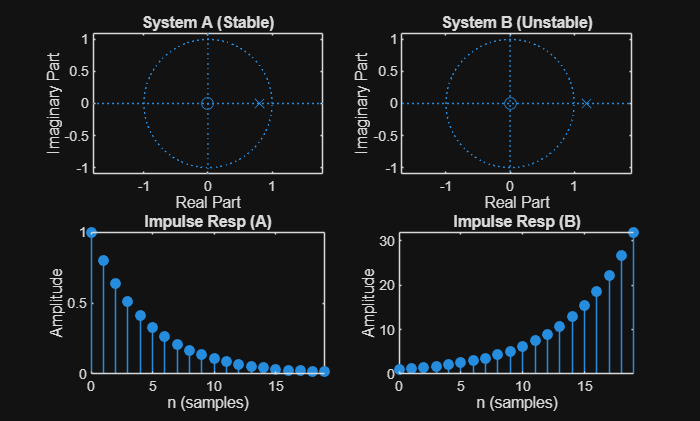

%% Task 4: Stability & Poles
% System A pole at 0.8 
% System B pole at 1.2

figure(2);
subplot(2,2,1); zplane(1, [1, -0.8]); title('System A (Stable)');
subplot(2,2,2); zplane(1, [1, -1.2]); title('System B (Unstable)');

% Look at the Impulse Responses
subplot(2,2,3); impz(1, [1, -0.8], 20); title('Impulse Resp (A)');
subplot(2,2,4); impz(1, [1, -1.2], 20); title('Impulse Resp (B)');

% System B is unstable because its pole |1.2| > 1 

System A is stable because its pole is at 0.8, which is inside the unit circle. If you give this system a quick nudge with an impulse, the output eventually settles back to zero. It stays within bounds.

System B is unstable because its pole is at 1.2, which sits outside the unit circle. Because the pole is greater than 1, the system has a feedback effect that grows over time instead of decaying. If you look at the step response or impulse response plots, you will see the values climbing higher and higher toward infinity rather than leveling off.

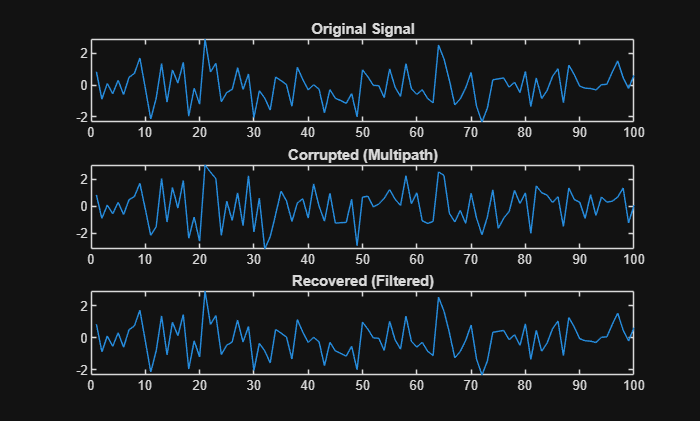

%% Task 5: Wireless Multipath Recovery 
% alpha = 0.8;
delay = 11;
original_x = randn(1, 100); % Random data 

% Distortion: y[n] = x[n] - alpha * x[n - delay] 
b_distort = [1, zeros(1, delay-1), -alpha];
corrupted_y = filter(b_distort, 1, original_x);
% We put the distortion coefficients in denominator to flip effects
recovered_x = filter(1, b_distort, corrupted_y);

figure(3);
subplot(3,1,1); plot(original_x); title('Original Signal');
subplot(3,1,2); plot(corrupted_y); title('Corrupted (Multipath)');
subplot(3,1,3); plot(recovered_x); title('Recovered (Filtered)');